# **Plate mode with respect to RADIUS**

**2024-01-18 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

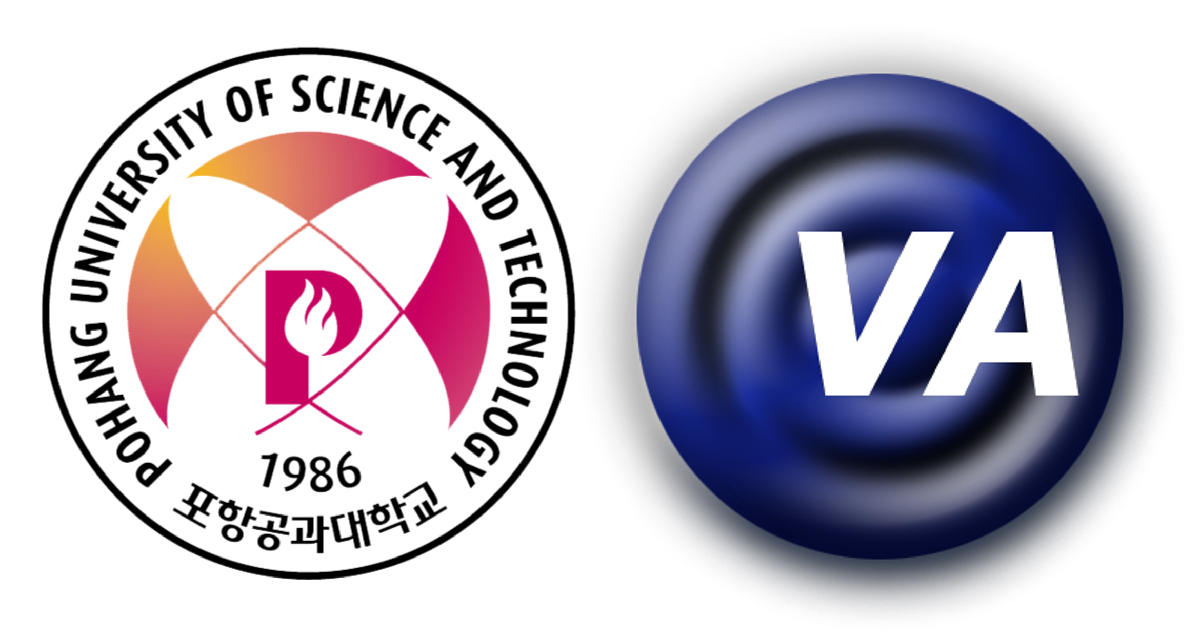

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

close all
clf 
clear

Env.MPH.PATH    = 'D:\wj\Back Up\0 -Doctoral research\M - MATLAB - SPPALs\40\';
Env.FIG.UNIT    = 'inches';
Env.FIG.WIDTH   = 3.25;
Env.FIG.HEIGHT  = 2.5;

Study.FREQ_START    = 20e3;
Study.FREQ_STOP     = 50e3;
Study.FREQ_STEP_SOLID ...
                    = 10;
Study.FREQ_STEP_ACO ...
                    = 100;
Study.freqSolid     = Study.FREQ_START:Study.FREQ_STEP_SOLID:Study.FREQ_STOP;
Study.freqAcoustic  = Study.FREQ_START:Study.FREQ_STEP_ACO:Study.FREQ_STOP;
Study.freqAcousticSecDiff = [500, 630, 800, 1e3, 1.25e3, 1.6e3, 2e3, 2.5e3, 3.15e3, 4e3, 5e3, 6.3e3, 8e3, 1e4, 1.25e4, 1.6e4, 2e4];

Study.MODE_NO_START = 4;
Study.MODE_NO_STOP  = 4;
Study.mode          = Study.MODE_NO_START:Study.MODE_NO_STOP;
Study.nMode         = length(Study.mode);

Study.Z_START       = 0.1;
Study.Z_STOP        = 2;
Study.Z_STOP_ACO_SEC= 1;
Study.N_Z           = 1000;

Study.TH_START      = -90/180*pi;
Study.TH_STOP       = 90/180*pi;
Study.N_TH          = 361;

% Load the material properties
Mat = import_material('materials_OBS_loss_D.txt')

Mat = 4×14 table
                              Mat           rho             Y33                    Y11             nu      Q      eps33      d33        g33       k33        d31        DF            v3                v1      
                       _________________    ____    ___________________    ___________________    ____    ____    _____    ________    ______    _____    _________    _____    ______________    ______________

    Aluminum           "Aluminum"           2780    7.2e+10+3.6e+07i   


%%
Air.c = 343;
Air.rho = 1.21;
%%

Plate.FREQ = 40e3;
Plate.RADIUS = 37e-3;
Plate.THICKNESS = 1e-3;
Plate.LAMBDA = [3.01146
                6.20540
                9.37084
                12.52518
                15.67466
                18.82161
                21.96703
                25.11160
                28.25549
                31.39893
                34.54204
                37.63490
                40.82757
                43.97008
                47.11248
                50.25478];
Plate.tStep = Air.c/Plate.FREQ/2; %%
Plate.freqSteppedPlate = 42740; %% Need to improve



$$$f_i = \frac{\lambda_i^2t}{2\pi r^2} \sqrt{\frac{E}{12\rho(1-\nu^2)}}$$$


Itao, K. and S.H. Crandall, Natural Modes and Natural Frequencies of Uniform, Circular, Free-Edge Plates. Journal of Applied Mechanics, 1979. 46(2): p. 448-453.

computePlateFreq       = @(r, t, LAMBDA, rho, E, nu) LAMBDA^2*t/(2*pi*r^2)*sqrt(E/(12*rho*(1-nu^2)));


$$$r = \sqrt{\frac{\lambda_i^2t}{2\pi} \sqrt{\frac{E}{12\rho(1-\nu^2)}}}$$$


computePlateRadius      = @(freq, t, LAMBDA, rho, E,  nu) sqrt((LAMBDA^2*t)/(2*pi*freq)*sqrt(E/(12*rho*(1-nu^2))));


$$$t = \frac{2\pi f_i r^2}{\lambda_i^2} \sqrt{\frac{12\rho(1-\nu^2)}{E}}$$$


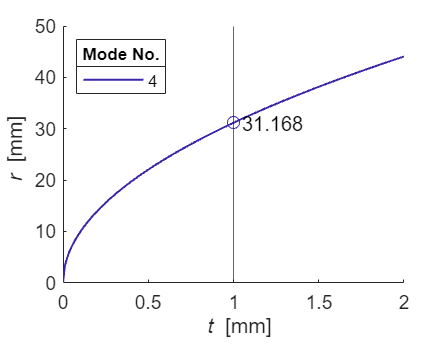

computePlateThickness   = @(freq, r, LAMBDA, rho, E, nu) freq*(2*pi*r.^2)/(LAMBDA^2)/sqrt(E/(12*rho*(1-nu^2)));

t = 0:1e-5:2e-3;
Plate.rCPT = zeros(length(t),Study.nMode);
r = 0:1e-3:100e-3;
Plate.tCPT = zeros(length(r),Study.nMode);

for iMode = 1:Study.nMode
    Plate.rCPT(:,iMode) = computePlateRadius(Plate.FREQ, t, Plate.LAMBDA(Study.mode(iMode)), ...
        Mat.rho('Aluminum'), abs(Mat.Y33('Aluminum')), Mat.nu('Aluminum'));
    Plate.tCPT(:,iMode) = computePlateThickness(Plate.FREQ, r, Plate.LAMBDA(Study.mode(iMode)), ...
        Mat.rho('Aluminum'), abs(Mat.Y33('Aluminum')), Mat.nu('Aluminum'));
end

figurePlateRadius = figure('Name','t vs. r', 'Units','inches', ...
    'OuterPosition',[0 0 Env.FIG.WIDTH Env.FIG.HEIGHT]);
axesPlateRadius = axes('Parent',figurePlateRadius);
hold(axesPlateRadius,'on');
C = colororder(parula(Study.nMode+1));
colororder(C(1:Study.nMode,:));

xline(Plate.THICKNESS*1e3)
pPlateRadius = plot(t*1e3,Plate.rCPT*1e3,'LineWidth',1);

Plate.rCPT = Plate.rCPT(find(t == Plate.THICKNESS),:);
sPlateRadius = scatter(Plate.THICKNESS*1e3, Plate.rCPT*1e3);
text(repmat(Plate.THICKNESS,Study.nMode,1)*1.05e3, Plate.rCPT*1e3, arrayfun(@(x) num2str(x*1e3,'%.3f'), Plate.rCPT, 'UniformOutput', false))

xlabel('{\it t} [mm]')
ylabel('{\it r} [mm]')
lgdPlateRadius = legend(pPlateRadius, string(Study.mode),'Location','northwest','Orientation','vertical');
title(lgdPlateRadius, 'Mode No.')
hold(axesPlateRadius,'off');

if exist('modelComputePlateRadius','var') ~= 1
    modelComputePlateRadius = mphload('computePlateRadius.mph');
end
modelComputePlateRadius.hist.disable;

modelComputePlateRadius.param.set('Plate_freq',   [num2str(Plate.FREQ) ' [Hz]']);
modelComputePlateRadius.param.set('Plate_t',      [num2str(Plate.THICKNESS) ' [m]']);

Plate.rFEM = zeros(1,Study.nMode);
Plate.rStepFEM = cell(1, Study.nMode);

for iMode = 1:Study.nMode
    tic
    modelComputePlateRadius.param.set('Plate_rIV',      [num2str(Plate.rCPT(iMode)) ' [m]']);
    mphrun(modelComputePlateRadius,'std1')
    Plate.rFEM(iMode) = mphglobal(modelComputePlateRadius, 'Plate_r', 'dataset', 'dset1');
    Plate.freqFEM(iMode) = mphglobal(modelComputePlateRadius, 'abs(freq)', 'dataset', 'dset1');

    [tempR, tempZ] = meshgrid(0:1e-4:Plate.rFEM(iMode),0);
    tempCoord = [tempR(:) tempZ(:)]';
    tempW = real(mphinterp(modelComputePlateRadius, 'w', 'coord', tempCoord));
    iZeroCrossing = find(tempW(1:end-1).*tempW(2:end) <= 0);
    tempRZeroCrossing = tempR(iZeroCrossing);

    Plate.rStepFEM(iMode) = mat2cell(tempRZeroCrossing',length(tempRZeroCrossing),1);
    toc
end

Elapsed time is 16.521817 seconds.


% Mode  r_{CPT} r_{FEM} RE      RE      freq
%                       ↳ Relative error from CPT to FEM
%                               ↳ Relative error from FEM to CPT
% 1     [mm]    [mm]    [%]     [%]     [kHz]
disp([Study.mode' Plate.rCPT'*1e3 Plate.rFEM'*1e3 (Plate.rCPT-Plate.rFEM)'./Plate.rFEM'*1e2 (Plate.rFEM-Plate.rCPT)'./Plate.rCPT'*1e2 Plate.freqFEM'/1e3])

    4.0000   31.1680   30.7784    1.2659   -1.2500   39.8518



if exist('modelComputePlateImpedance','var') ~= 1
    modelComputePlateImpedance = mphload('computePlateImpedance.mph');
end
modelComputePlateImpedance.hist.disable;

modelComputePlateImpedance.param.set('Study_freqStart',   [num2str(Study.FREQ_START)  ' [Hz]']);
modelComputePlateImpedance.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_SOLID)     ' [Hz]']);
modelComputePlateImpedance.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)   ' [Hz]']);
modelComputePlateImpedance.param.set('Plate_t',           [num2str(Plate.THICKNESS)   ' [m]']);

Plate.zPlateFEM = zeros(length(Study.freqSolid),Study.nMode);
for iMode = 1:Study.nMode
    tic
    modelComputePlateImpedance.param.set('Plate_r',       [num2str(Plate.rFEM(iMode)) ' [m]']);
    mphrun(modelComputePlateImpedance,'std1')
    Plate.zPlateFEM(:,iMode) = mphevalpoint(modelComputePlateImpedance, '1[N]/solid.u_tZ', 'dataset', 'dset1','selection',1);
    toc
end

Elapsed time is 32.147565 seconds.


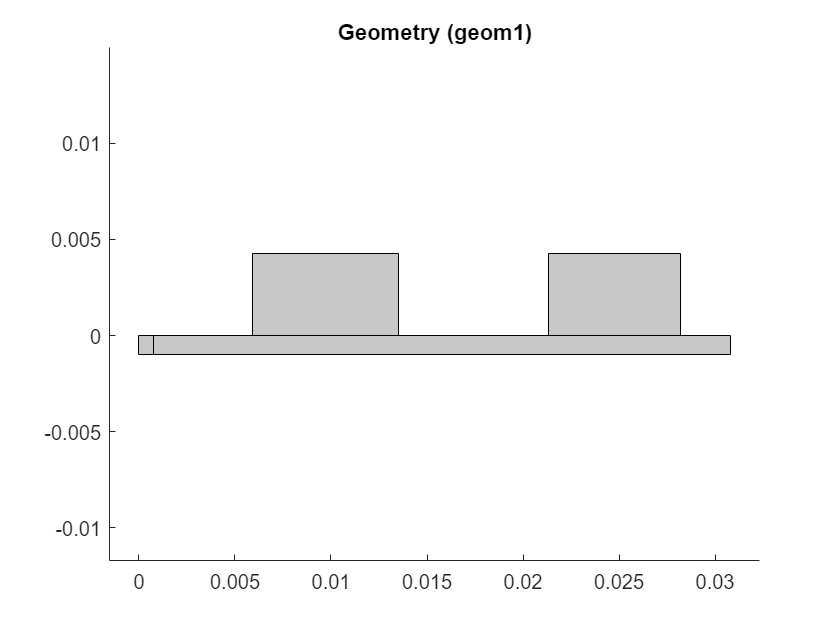

Elapsed time is 48.526372 seconds.


Plate.zSteppedPlateFEM = zeros(length(Study.freqSolid),Study.nMode);
figureSteppedPlateGeom = figure('Name','Stepped-Plate Geometries');
axesSteppedPlateGeom = axes('Parent',figureSteppedPlateGeom);
% hold(axesSteppedPlateGeom,'on');
for iMode = 1:Study.nMode
    tic
    if exist('modelComputeSteppedPlateImpedance','var') ~= 1
        modelComputeSteppedPlateImpedance = mphload('computeSteppedPlateImpedance.mph');
    end
    modelComputeSteppedPlateImpedance.hist.disable;
    
    modelComputeSteppedPlateImpedance.param.set('Study_freqStart',   [num2str(Study.FREQ_START)  ' [Hz]']);
    modelComputeSteppedPlateImpedance.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_SOLID)    ' [Hz]']);
    modelComputeSteppedPlateImpedance.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)   ' [Hz]']);
    modelComputeSteppedPlateImpedance.param.set('Plate_t',           [num2str(Plate.THICKNESS)   ' [m]']);
    modelComputeSteppedPlateImpedance.param.set('Plate_r',           [num2str(Plate.rFEM(iMode)) ' [m]']);
    modelComputeSteppedPlateImpedance.param.set('Plate_tStep',       [num2str(Plate.tStep) ' [m]']);

    tempRStep = cell2mat(Plate.rStepFEM(iMode));
    for iStep = 1:fix(length(tempRStep)/2)  % fix(5/2)=2, fix(6/2)=3
        tag = modelComputeSteppedPlateImpedance.geom('geom1').feature.uniquetag('r');
        modelComputeSteppedPlateImpedance.geom('geom1').feature.create(tag, 'Rectangle');
        modelComputeSteppedPlateImpedance.geom('geom1').feature(tag).set('size', [tempRStep(2*iStep)-tempRStep(2*iStep-1) Plate.tStep]);
        modelComputeSteppedPlateImpedance.geom('geom1').feature(tag).set('pos',  [tempRStep(2*iStep-1) 0]);
    end
    subplot(Study.nMode,1,iMode)
    mphgeom(modelComputeSteppedPlateImpedance)
    drawnow
    mphrun(modelComputeSteppedPlateImpedance,'std1')
    
    Plate.zSteppedPlateFEM(:,iMode) = mphevalpoint(modelComputeSteppedPlateImpedance, '1[N]/solid.u_tZ', 'dataset', 'dset1','selection',1);
    clear modelComputeSteppedPlateImpedance
    toc
end

% hold(axesSteppedPlateGeom,'off');

Plate.zSteppedPlateAcousticFEM = zeros(length(Study.freqAcoustic),Study.nMode);
Aco.tfrSteppedPlateFEM  = zeros(length(Study.freqAcoustic),Study.nMode); % tfr: Transmitting Force Response

% for iMode = 1:1
for iMode = 1:Study.nMode
    tic
    tempFilename = ['computeSteppedPlateAcoustic_r=' num2str(Plate.rFEM(iMode)*1e3,'%2.1f')...
        '_t=' num2str(Plate.THICKNESS*1e3,'%2.1f')...
        '_m=' num2str(Study.mode(iMode),'%d')...
        '_f=' num2str(Plate.FREQ/1e3, '%g')...
        '.mph'];
    if exist(tempFilename,'file') == 2
        modelComputeSteppedPlateAcoustic = mphload(tempFilename);
    elseif exist('modelComputeSteppedPlateAcoustic','var') ~= 1
        modelComputeSteppedPlateAcoustic = mphload('computeSteppedPlateAcoustic.mph');
        modelComputeSteppedPlateAcoustic.hist.disable;
        
        modelComputeSteppedPlateAcoustic.param.set('Study_freqStart',   [num2str(Study.FREQ_START)  ' [Hz]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_ACO)   ' [Hz]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)   ' [Hz]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_zStart',      [num2str(Study.Z_START)     ' [m]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_zStop',       [num2str(Study.Z_STOP)      ' [m]']);
        modelComputeSteppedPlateAcoustic.param.set('Study_thStart',     num2str(Study.TH_START));
        modelComputeSteppedPlateAcoustic.param.set('Study_thStop',      num2str(Study.TH_STOP));
        modelComputeSteppedPlateAcoustic.param.set('Plate_t',           [num2str(Plate.THICKNESS)   ' [m]']);
        modelComputeSteppedPlateAcoustic.param.set('Plate_r',           [num2str(Plate.rFEM(iMode)) ' [m]']);
        modelComputeSteppedPlateAcoustic.param.set('Plate_tStep',       [num2str(Plate.tStep) ' [m]']);
    
        tempRStep = cell2mat(Plate.rStepFEM(iMode));
        for iStep = 1:fix(length(tempRStep)/2)  % fix(5/2)=2, fix(6/2)=3
            tag = modelComputeSteppedPlateAcoustic.geom('geom1').feature.uniquetag('r');
            modelComputeSteppedPlateAcoustic.geom('geom1').feature.create(tag, 'Rectangle');
            modelComputeSteppedPlateAcoustic.geom('geom1').feature(tag).set('size', [tempRStep(2*iStep)-tempRStep(2*iStep-1) Plate.tStep]);
            modelComputeSteppedPlateAcoustic.geom('geom1').feature(tag).set('pos',  [tempRStep(2*iStep-1) 0]);
        end
        mphrun(modelComputeSteppedPlateAcoustic,'std1')
        mphsave(modelComputeSteppedPlateAcoustic,[Env.MPH.PATH tempFilename])
    end

    Plate.zSteppedPlateAcousticFEM(:,iMode) = ...
        mphevalpoint(modelComputeSteppedPlateAcoustic, '1[N]/solid.u_tZ', 'dataset', 'dset1','selection',1);
    [Study.z(:,:,iMode), Aco.pcSteppedPlateFEM(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateAcoustic,{'z' 'subst(acpr.efc1.Lp_pext,r,0)'},'dataset','grid1');
    [Study.th(:,:,iMode), Aco.bpSteppedPlateFEM(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateAcoustic,{'th' 'subst(acpr.efc1.Lp_pext,r,sin(th),z,cos(th))'},'dataset','grid2');

    clear modelComputeSteppedPlateAcoustic
    toc
end

Elapsed time is 36.680684 seconds.


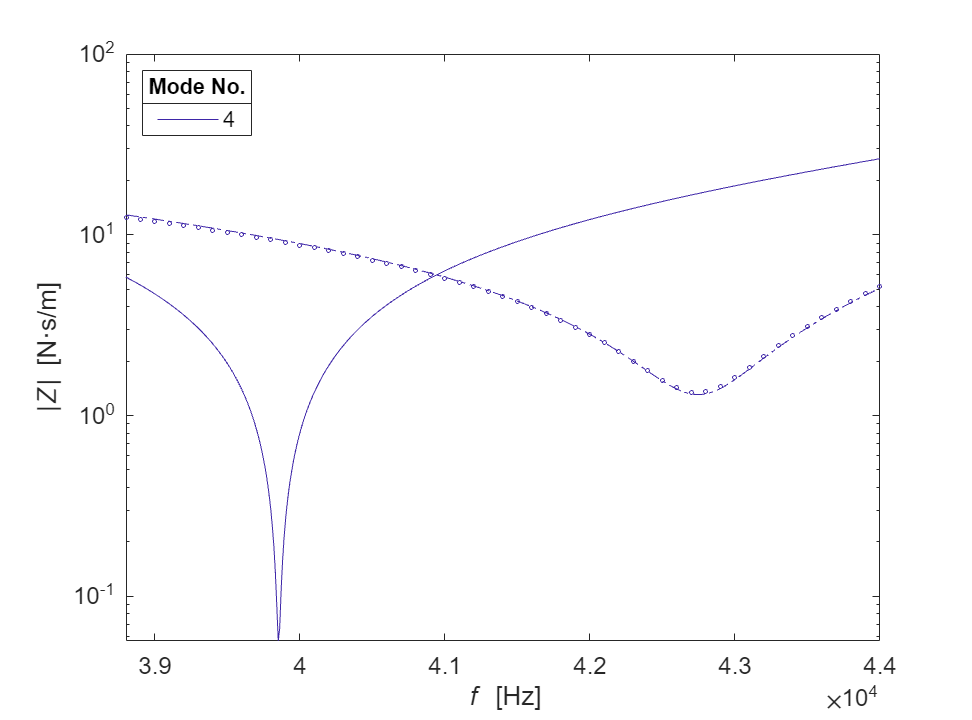

figurePlateImpedance = figure('Name','f vs. Z','Units','inches','Position',[0 0 6.75 5]);

axesPlateImpedance = axes('Parent',figurePlateImpedance);
hold(axesPlateImpedance,'on');
C = colororder(parula(Study.nMode+1));
colororder(C(1:Study.nMode,:));

pPlateImpedance = semilogy(Study.freqSolid, abs(Plate.zPlateFEM));
pSteppedPlateImpedance = semilogy(Study.freqSolid, abs(Plate.zSteppedPlateFEM),'-.');
pSteppedPlateImpedanceAcoustic = semilogy(Study.freqAcoustic, abs(Plate.zSteppedPlateAcousticFEM),'o','MarkerSize',2);

set(axesPlateImpedance,'YMinorTick','on','YScale','log','FontSize',12);
box(axesPlateImpedance,'on');
hold(axesPlateImpedance,'off');
xlabel('{\itf} [Hz]')
ylabel('|{\itZ}| [N·s/m]')
xlim(axesPlateImpedance,[Plate.FREQ*0.97 Plate.FREQ*1.1]);
% ylim(axesPlateImpedance,[5e-2 10]);
lgdPlateImpedance = legend(pPlateImpedance, string(Study.MODE_NO_START:Study.MODE_NO_STOP),'Location','northwest','Orientation','vertical');
title(lgdPlateImpedance, 'Mode No.')
hold(axesPlateImpedance,'off');

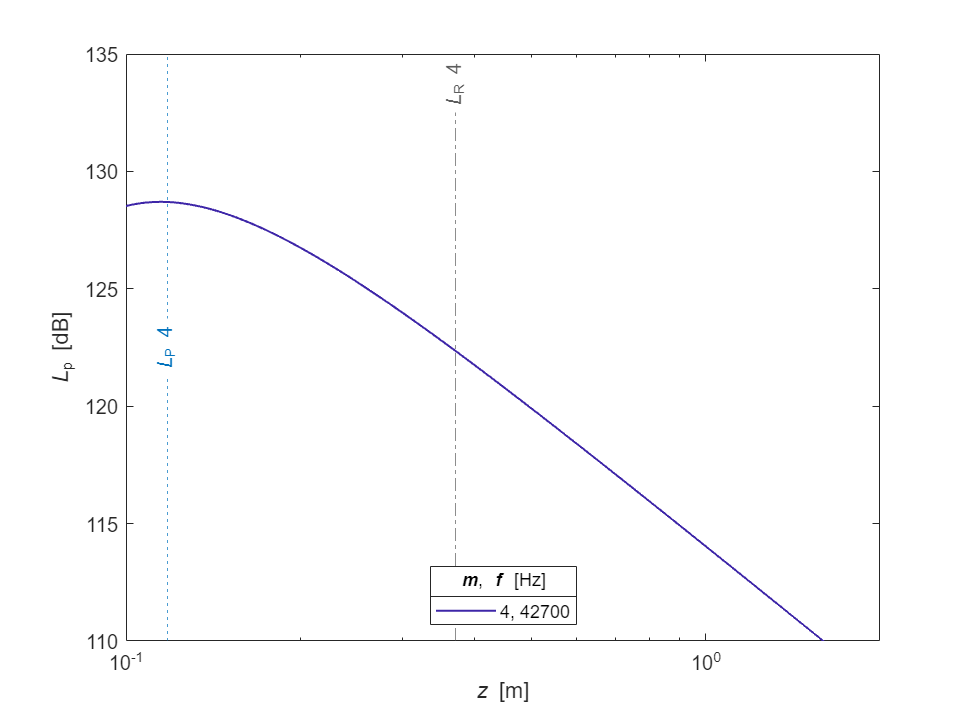

%% TODO: Absorption location

% for a plane circular piston
% Kinsler, L.E., Fundamentals of acoustics / Lawrence E. Kinsler ... [et al.]. 4th ed. 2000, New York: New York : Wiley.
% p.180
Aco.computeRayleighLength       = @(a, f, c) pi*a.^2.*f./c; % S/lambda
Aco.computeAxialPeakDistance    = @(a, f, c) (a.*f./c-c./(4.*f)).*a; % (7.4.10)
Aco.computeAxialNullDistance    = @(a, f, c) (a.*f./(2.*c)-c./(2.*f)).*a; % (7.4.11)

[~,tempI] = min(abs(Plate.zSteppedPlateAcousticFEM),[],1);

figurePropagationCurvePeakFreq = figure('Name','z vs. SPL','Units','inches','Position',[0 0 6.75 5]);

axesPropagationCurvePeakFreq = axes('Parent',figurePropagationCurvePeakFreq);
hold(axesPropagationCurvePeakFreq,'on');
C = colororder(parula(Study.nMode+1));
colororder(repmat(C(1:Study.nMode,:),3,1));

for iMode = 1:Study.nMode
    pPropagationCurvePeakFreqAcoustic = ...
        plot(Study.z(tempI(iMode),:,iMode), Aco.pcSteppedPlateFEM(tempI(iMode),:,iMode), ...
        'DisplayName',[num2str(Study.mode(iMode)) ', ' num2str(Study.freqAcoustic(tempI(iMode)))], ...
        'LineWidth',1);
end

pRayleighLengthPeakFreqAcoustic = xline(Aco.computeRayleighLength(Plate.rFEM,Study.freqAcoustic(tempI),Air.c),...
    '-.',repmat("{\itL}_R ",1,Study.nMode)'+string(Study.mode)','HandleVisibility','Off','Color','#5C5C5C', ...
    'LabelHorizontalAlignment','center');
pAxialPeakDistanceFreqAcoustic = xline(Aco.computeAxialPeakDistance(Plate.rFEM,Study.freqAcoustic(tempI),Air.c),...
    ':',repmat("{\itL}_P ",1,Study.nMode)'+string(Study.mode)','HandleVisibility','Off','Color','#0072BD', ...
    'LabelVerticalAlignment','middle','LabelHorizontalAlignment','center');
pAxialNullDistanceFreqAcoustic = xline(Aco.computeAxialNullDistance(Plate.rFEM,Study.freqAcoustic(tempI),Air.c),...
    '--',repmat("{\itL}_N ",1,Study.nMode)'+string(Study.mode)','HandleVisibility','Off','Color','#D95319', ...
    'LabelHorizontalAlignment','center');

box(axesPropagationCurvePeakFreq,'on');
hold(axesPropagationCurvePeakFreq,'off');
xlabel('{\itz} [m]')
ylabel('{\itL}_{p} [dB]')
xlim(axesPropagationCurvePeakFreq,[Study.Z_START Study.Z_STOP]);
ylim(axesPropagationCurvePeakFreq,[110 135]);
set(axesPropagationCurvePeakFreq,'XScale','log');
lgdPropagationCurvePeakFreq = legend(axesPropagationCurvePeakFreq,'Location','south','Orientation','vertical');
title(lgdPropagationCurvePeakFreq, '{\itm}{\rm,} {\itf} {\rm[Hz]}')
hold(axesPropagationCurvePeakFreq,'off');

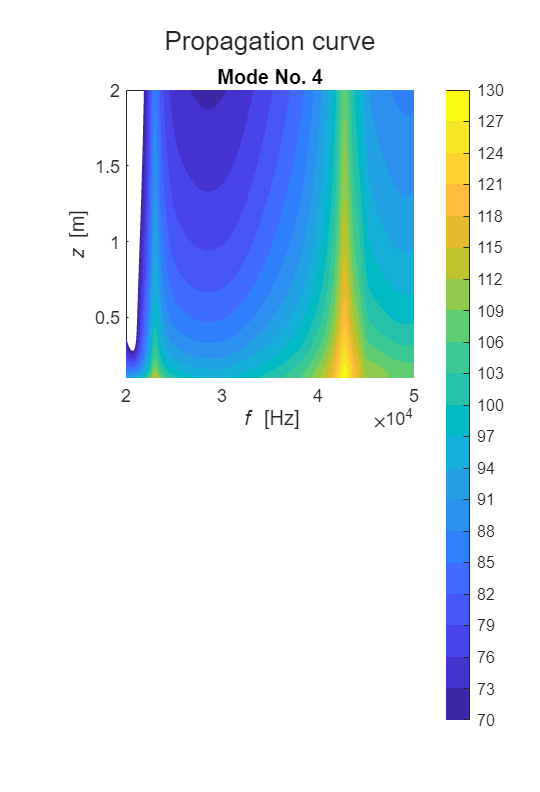

figurePropagationCurve = figure('Name','f, z vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tilePropagationCurve = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
C = parula(20);
colormap(C);

for iMode = 1:Study.nMode
    axesPropagationCurve = nexttile(tilePropagationCurve);
    hold(axesPropagationCurve,'on');
    
    [tempF, tempZ] = meshgrid(Study.freqAcoustic, Study.z(1,:,iMode));
    pPropagationCurve = contourf(tempF, tempZ, ...
        Aco.pcSteppedPlateFEM(:,:,iMode)',70:3:130,'EdgeColor','none');
    % pPropagationCurve = contourf(tempF, tempZ, ...
    %     Aco.pcSteppedPlateFEM(:,:,iMode)'-repmat(max(Aco.pcSteppedPlateFEM(:,:,iMode),[],2),1,Study.N_Z)',20,'EdgeColor','none');
    box(axesPropagationCurve,'on');
    hold(axesPropagationCurve,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\itz} [m]')
    title(axesPropagationCurve, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesPropagationCurve,[Study.Z_START Study.Z_STOP]);
    clim(axesPropagationCurve,[70 130]);
    hold(axesPropagationCurve,'off');
end
cbPropagationCurve = colorbar(axesPropagationCurve,'Ticks',70:3:130);
cbPropagationCurve.Layout.Tile = 'east';
title(tilePropagationCurve,'Propagation curve')

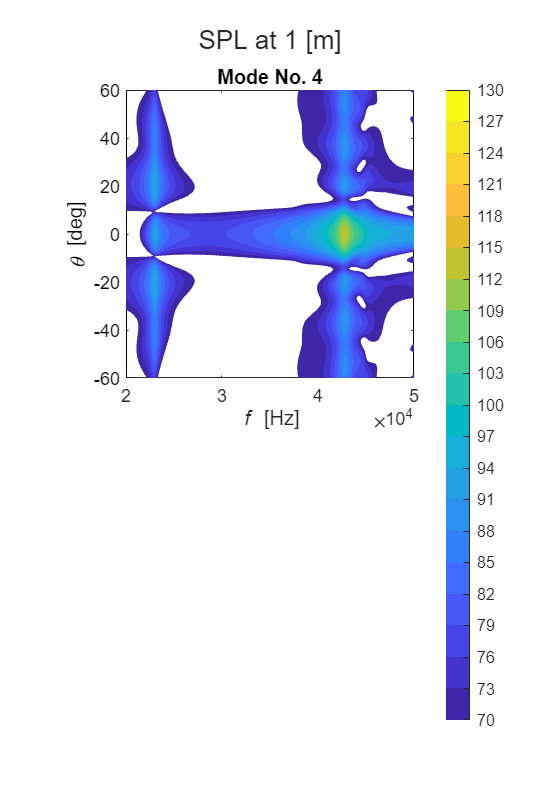

figureBeamPattern = figure('Name','f, th vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tileBeamPattern = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
C = parula(20);
colormap(C);

for iMode = 1:Study.nMode
    axesBeamPattern = nexttile(tileBeamPattern);
    hold(axesBeamPattern,'on');

    [tempF, tempTh] = meshgrid(Study.freqAcoustic, Study.th(1,:,iMode));
    pBeamPattern = contourf(tempF, tempTh/pi*180, ...
        Aco.bpSteppedPlateFEM(:,:,iMode)',70:3:130,'EdgeColor','none');

    set(axesBeamPattern,'YColor',[0 0 0]);
    box(axesBeamPattern,'on');
    hold(axesBeamPattern,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\it\theta} [deg]')
    title(axesBeamPattern, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesBeamPattern,[Study.TH_START/pi*180/1.5 Study.TH_STOP/pi*180/1.5]);
    clim(axesBeamPattern,[70 130])
    hold(axesBeamPattern,'off');
end
cbBeamPattern = colorbar(axesBeamPattern,'Ticks',70:3:130);
cbBeamPattern.Layout.Tile = 'east';
title(tileBeamPattern,'SPL at 1 [m]')

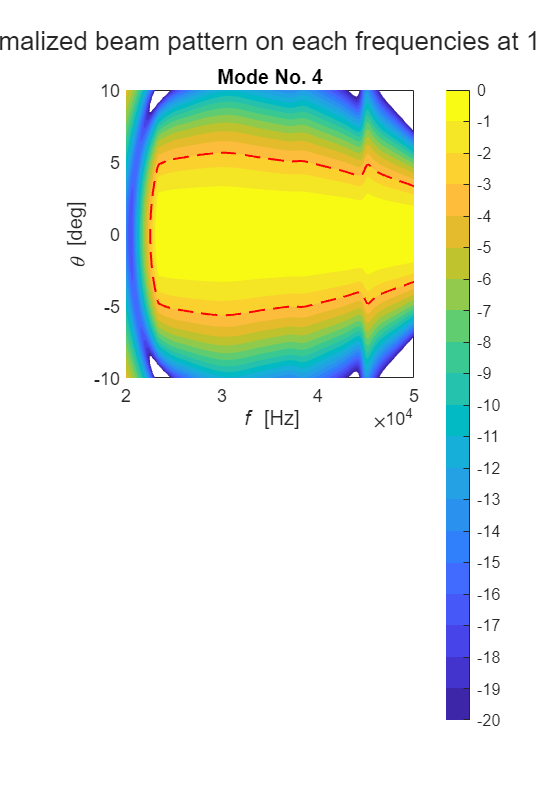

figureBeamPatternNormalized = figure('Name','f, th vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tileBeamPatternNormalized = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
C = parula(20);
colormap(C);

for iMode = 1:Study.nMode
    axesBeamPatternNormalized = nexttile(tileBeamPatternNormalized);
    hold(axesBeamPatternNormalized,'on');
    
    [tempF, tempTh] = meshgrid(Study.freqAcoustic, Study.th(1,:,iMode));
    Aco.bpNormalizedSteppedPlateFEM = Aco.bpSteppedPlateFEM(:,:,iMode)'-repmat(max(Aco.bpSteppedPlateFEM(:,:,iMode),[],2),1,Study.N_TH)';
    pBeamPatternNormalized = contourf(tempF, tempTh/pi*180, ...
        Aco.bpNormalizedSteppedPlateFEM,-20:0,'EdgeColor','none');
    pHalfPowerBeamWidthNormalized = contour(tempF, tempTh/pi*180, ...
        Aco.bpNormalizedSteppedPlateFEM,[-3 -3],'--r','LineWidth',1);

    box(axesBeamPatternNormalized,'on');
    hold(axesBeamPatternNormalized,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\it\theta} [deg]')
    title(axesBeamPatternNormalized, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesBeamPatternNormalized,[Study.TH_START/pi*180/9 Study.TH_STOP/pi*180/9]);
    clim(axesBeamPatternNormalized,[-20 0])
    hold(axesBeamPatternNormalized,'off');
end
cbBeamPatternNormalized = colorbar(axesBeamPatternNormalized,'Ticks',-20:0);
cbBeamPatternNormalized.Layout.Tile = 'east';
title(tileBeamPatternNormalized,'Normalized beam pattern on each frequencies at 1 [m]')

Xdcr.l = [10.2e-3 16e-3 18.0e-3 28.6e-3];      % Length of element of transducer [m]
Xdcr.r = [10e-3 10e-3 10e-3 0.75e-3];          % Radius of element of transducer [m]
Xdcr.nPiezo = 4;                            % Number of element of piezostack [1]
Xdcr.V = 40;                                % Operating voltage of transducer [1]

%% Optimzation routine 현재 하나의 모드만 계산되도록 되어있음. 개선해야함.

Xdcr.l4IV = Xdcr.l(4);
Xdcr.l4LB = Xdcr.l4IV*0.8;
Xdcr.l4UB = Xdcr.l4IV*1.2;

for iMode = 1:Study.nMode
    tic
    if exist('modelOptimizeSteppedPlateTransducer','var') ~= 1
        modelOptimizeSteppedPlateTransducer = mphload('OptimizeSteppedPlateTransducer.mph');
    end
    modelOptimizeSteppedPlateTransducer.hist.disable;
    
    modelOptimizeSteppedPlateTransducer.param.set('Study_freqStart',   [num2str(Study.FREQ_START)  ' [Hz]']);
    modelOptimizeSteppedPlateTransducer.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_SOLID)    ' [Hz]']);
    modelOptimizeSteppedPlateTransducer.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)   ' [Hz]']);
    modelOptimizeSteppedPlateTransducer.param.set('Plate_t',           [num2str(Plate.THICKNESS)   ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Plate_r',           [num2str(Plate.rFEM(iMode)) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Plate_tStep',       [num2str(Plate.tStep) ' [m]']);

    tempRStep = cell2mat(Plate.rStepFEM(iMode));
    for iStep = 1:fix(length(tempRStep)/2)  % fix(5/2)=2, fix(6/2)=3
        tag = modelOptimizeSteppedPlateTransducer.geom('geom1').feature.uniquetag('r');
        modelOptimizeSteppedPlateTransducer.geom('geom1').feature.create(tag, 'Rectangle');
        modelOptimizeSteppedPlateTransducer.geom('geom1').feature(tag).set('size', [tempRStep(2*iStep)-tempRStep(2*iStep-1) Plate.tStep]);
        modelOptimizeSteppedPlateTransducer.geom('geom1').feature(tag).set('pos',  [tempRStep(2*iStep-1) 0]);
    end

    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_l1',           [num2str(Xdcr.l(1)) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_l2',           [num2str(Xdcr.l(2)) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_l3',           [num2str(Xdcr.l(3)) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_l4',           [num2str(Xdcr.l(4)) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_r1',           [num2str(Xdcr.r(1)) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_r2',           [num2str(Xdcr.r(2)) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_r3',           [num2str(Xdcr.r(3)) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_r4',           [num2str(Xdcr.r(4)) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_nPiezo',       num2str(Xdcr.nPiezo));
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_V',            [num2str(Xdcr.V)    ' [V]']);

    modelOptimizeSteppedPlateTransducer.param.set('Plate_freqSteppedPlate',           [num2str(Plate.freqSteppedPlate) ' [Hz]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_l4_iv',           [num2str(Xdcr.l4IV) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_l4_lb',           [num2str(Xdcr.l4LB) ' [m]']);
    modelOptimizeSteppedPlateTransducer.param.set('Xdcr_l4_ub',           [num2str(Xdcr.l4UB) ' [m]']);

    mphrun(modelOptimizeSteppedPlateTransducer,'std1')

    tempL4 = mphglobal(modelOptimizeSteppedPlateTransducer, 'Xdcr_l4', 'dataset', 'dset1')
    
    Xdcr.l(4) = tempL4(1);
    clear modelOptimizeSteppedPlateTransducer
    toc
end

tempL4 =     0.0272
    0.0272


Elapsed time is 56.935910 seconds.


% Distributed Parameter Model
DPM.u5fun = u5DPM(Mat);
DPM.u5 = DPM.u5fun(repmat(Study.freqSolid',1,Study.nMode),Plate.zSteppedPlateFEM,Xdcr.l(1),Xdcr.l(2),Xdcr.l(3),Xdcr.l(4),Xdcr.r(1),Xdcr.r(2),Xdcr.r(3),Xdcr.r(4),Xdcr.nPiezo,Xdcr.V);

% for iMode = 1:1
for iMode = 1:Study.nMode
    tic
    tempFilename = ['computeSteppedPlateTransducer_r=' num2str(Plate.rFEM(iMode)*1e3,'%2.1f')...
        '_t=' num2str(Plate.THICKNESS*1e3,'%2.1f')...
        '_m=' num2str(Study.mode(iMode),'%d')...
        '_f=' num2str(Plate.FREQ/1e3, '%g')...
        '.mph'];
    if exist(tempFilename,'file') == 2
        modelComputeSteppedPlateTransducer = mphload(tempFilename);
    elseif exist('modelComputeSteppedPlateTransducer','var') ~= 1
        modelComputeSteppedPlateTransducer = mphload('computeSteppedPlateTransducer.mph');
        modelComputeSteppedPlateTransducer.hist.disable;
        
        modelComputeSteppedPlateTransducer.param.set('Study_freqStart',   [num2str(Study.FREQ_START)  ' [Hz]']);
        modelComputeSteppedPlateTransducer.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_ACO)   ' [Hz]']);
        modelComputeSteppedPlateTransducer.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)   ' [Hz]']);
        modelComputeSteppedPlateTransducer.param.set('Study_zStart',      [num2str(Study.Z_START)     ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Study_zStop',       [num2str(Study.Z_STOP)      ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Study_thStart',     num2str(Study.TH_START));
        modelComputeSteppedPlateTransducer.param.set('Study_thStop',      num2str(Study.TH_STOP));
        modelComputeSteppedPlateTransducer.param.set('Plate_t',           [num2str(Plate.THICKNESS)   ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Plate_r',           [num2str(Plate.rFEM(iMode)) ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Plate_tStep',       [num2str(Plate.tStep) ' [m]']);
    
        tempRStep = cell2mat(Plate.rStepFEM(iMode));
        for iStep = 1:fix(length(tempRStep)/2)  % fix(5/2)=2, fix(6/2)=3
            tag = modelComputeSteppedPlateTransducer.geom('geom1').feature.uniquetag('r');
            modelComputeSteppedPlateTransducer.geom('geom1').feature.create(tag, 'Rectangle');
            modelComputeSteppedPlateTransducer.geom('geom1').feature(tag).set('size', [tempRStep(2*iStep)-tempRStep(2*iStep-1) Plate.tStep]);
            modelComputeSteppedPlateTransducer.geom('geom1').feature(tag).set('pos',  [tempRStep(2*iStep-1) 0]);
        end

        modelComputeSteppedPlateTransducer.param.set('Xdcr_l1',           [num2str(Xdcr.l(1)) ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Xdcr_l2',           [num2str(Xdcr.l(2)) ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Xdcr_l3',           [num2str(Xdcr.l(3)) ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Xdcr_l4',           [num2str(Xdcr.l(4)) ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Xdcr_r1',           [num2str(Xdcr.r(1)) ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Xdcr_r2',           [num2str(Xdcr.r(2)) ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Xdcr_r3',           [num2str(Xdcr.r(3)) ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Xdcr_r4',           [num2str(Xdcr.r(4)) ' [m]']);
        modelComputeSteppedPlateTransducer.param.set('Xdcr_nPiezo',       num2str(Xdcr.nPiezo));
        modelComputeSteppedPlateTransducer.param.set('Xdcr_V',            [num2str(Xdcr.V)    ' [V]']);

        mphrun(modelComputeSteppedPlateTransducer,'std1')               
        mphsave(modelComputeSteppedPlateTransducer,[Env.MPH.PATH tempFilename])
    end

    Plate.uSteppedPlateTransducerFEM(:,iMode) = ...
        mphevalpoint(modelComputeSteppedPlateTransducer, 'solid.u_tZ', 'dataset', 'dset1','selection','box1');

    clear modelComputeSteppedPlateTransducer
    toc
end

Elapsed time is 3.125861 seconds.


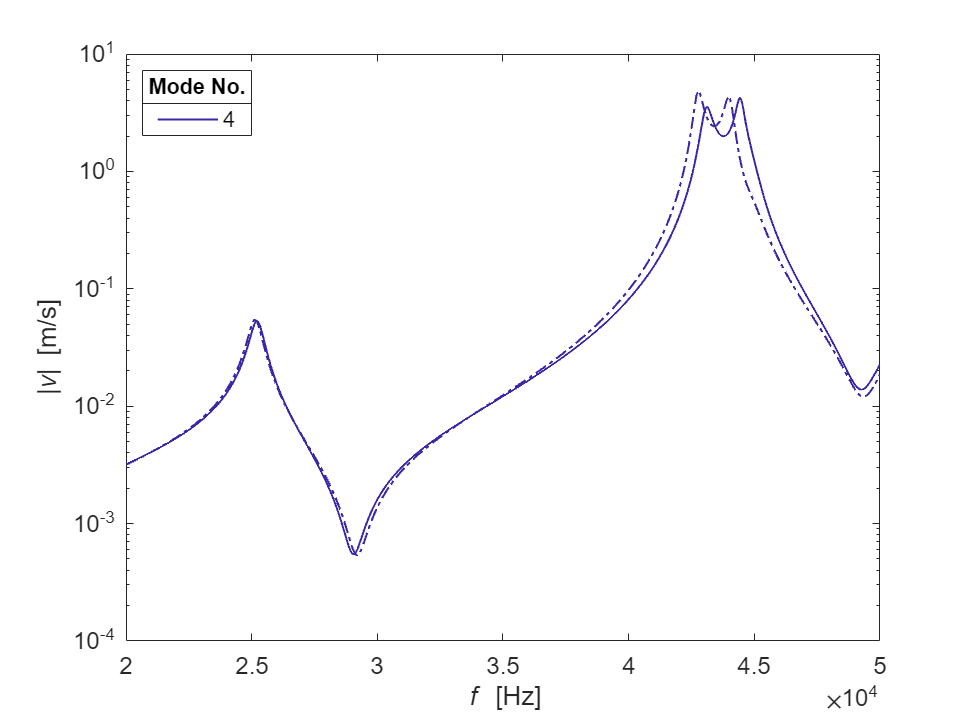

figureU5DPM = figure('Name','f vs. Z','Units','inches','Position',[0 0 6.75 5]);

axesU5DPM = axes('Parent',figureU5DPM);
hold(axesU5DPM,'on');
C = colororder(parula(Study.nMode+1));
colororder(C(1:Study.nMode,:));

pU5DPM = semilogy(Study.freqSolid, abs(DPM.u5),'LineWidth',1);
pU5SteppedPlateTransducerFEM = semilogy(Study.freqAcoustic, abs(Plate.uSteppedPlateTransducerFEM),'LineWidth',1,'LineStyle','-.');

set(axesU5DPM,'YMinorTick','on','YScale','log','FontSize',12);
box(axesU5DPM,'on');
hold(axesU5DPM,'off');
xlabel('{\itf} [Hz]')
ylabel('|{\itv}| [m/s]')
% xlim(axesU5DPM,[Plate.FREQ*0.97 Plate.FREQ*1.2]);
% ylim(axesU5DPM,[1e-1 10]);
lgdU5DPM = legend(pU5DPM, string(Study.MODE_NO_START:Study.MODE_NO_STOP),'Location','northwest','Orientation','vertical');
title(lgdU5DPM, 'Mode No.')
hold(axesU5DPM,'off');

% for iMode = 1:1
for iMode = 1:Study.nMode
    tic
    tempFilename = ['computeSteppedPlateTransducerAcoustic_r=' num2str(Plate.rFEM(iMode)*1e3,'%2.1f')...
        '_t=' num2str(Plate.THICKNESS*1e3,'%2.1f')...
        '_m=' num2str(Study.mode(iMode),'%d')...
        '_f=' num2str(Plate.FREQ/1e3, '%g')...
        '.mph'];
    if exist(tempFilename,'file') == 2
        modelComputeSteppedPlateTransducerAcoustic = mphload(tempFilename);
    elseif exist('modelComputeSteppedPlateTransducerAcoustic','var') ~= 1
        modelComputeSteppedPlateTransducerAcoustic = mphload('computeSteppedPlateTransducerAcoustic.mph');
        modelComputeSteppedPlateTransducerAcoustic.hist.disable;
        
        modelComputeSteppedPlateTransducerAcoustic.param.set('Study_freqStart',   [num2str(Study.FREQ_START)  ' [Hz]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Study_freqStep',    [num2str(Study.FREQ_STEP_ACO)   ' [Hz]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Study_freqStop',    [num2str(Study.FREQ_STOP)   ' [Hz]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Study_zStart',      [num2str(Study.Z_START)     ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Study_zStop',       [num2str(Study.Z_STOP)      ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Study_thStart',     num2str(Study.TH_START));
        modelComputeSteppedPlateTransducerAcoustic.param.set('Study_thStop',      num2str(Study.TH_STOP));
        modelComputeSteppedPlateTransducerAcoustic.param.set('Plate_t',           [num2str(Plate.THICKNESS)   ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Plate_r',           [num2str(Plate.rFEM(iMode)) ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Plate_tStep',       [num2str(Plate.tStep) ' [m]']);
    
        tempRStep = cell2mat(Plate.rStepFEM(iMode));
        for iStep = 1:fix(length(tempRStep)/2)  % fix(5/2)=2, fix(6/2)=3
            tag = modelComputeSteppedPlateTransducerAcoustic.geom('geom1').feature.uniquetag('r');
            modelComputeSteppedPlateTransducerAcoustic.geom('geom1').feature.create(tag, 'Rectangle');
            modelComputeSteppedPlateTransducerAcoustic.geom('geom1').feature(tag).set('size', [tempRStep(2*iStep)-tempRStep(2*iStep-1) Plate.tStep]);
            modelComputeSteppedPlateTransducerAcoustic.geom('geom1').feature(tag).set('pos',  [tempRStep(2*iStep-1) 0]);
        end

        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_l1',           [num2str(Xdcr.l(1)) ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_l2',           [num2str(Xdcr.l(2)) ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_l3',           [num2str(Xdcr.l(3)) ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_l4',           [num2str(Xdcr.l(4)) ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_r1',           [num2str(Xdcr.r(1)) ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_r2',           [num2str(Xdcr.r(2)) ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_r3',           [num2str(Xdcr.r(3)) ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_r4',           [num2str(Xdcr.r(4)) ' [m]']);
        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_nPiezo',       num2str(Xdcr.nPiezo));
        modelComputeSteppedPlateTransducerAcoustic.param.set('Xdcr_V',            [num2str(Xdcr.V)    ' [V]']);

        mphrun(modelComputeSteppedPlateTransducerAcoustic,'std1')               
        mphsave(modelComputeSteppedPlateTransducerAcoustic,[Env.MPH.PATH tempFilename])
    end

    Plate.uSteppedPlateTransducerAcousticFEM(:,iMode) = ...
        mphevalpoint(modelComputeSteppedPlateTransducerAcoustic, 'solid.u_tZ', 'dataset', 'dset1','selection','box1');
    [Study.z(:,:,iMode), Aco.pcSteppedPlateTransducerFEM(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateTransducerAcoustic,{'z' 'subst(acpr.efc1.Lp_pext,r,0)'},'dataset','grid1');
    [Study.th(:,:,iMode), Aco.bpSteppedPlateTransducerFEM(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateTransducerAcoustic,{'th' 'subst(acpr.efc1.Lp_pext,r,sin(th),z,cos(th))'},'dataset','grid2');

    clear modelComputeSteppedPlateTransducerAcoustic
    toc
end

Elapsed time is 16.498970 seconds.


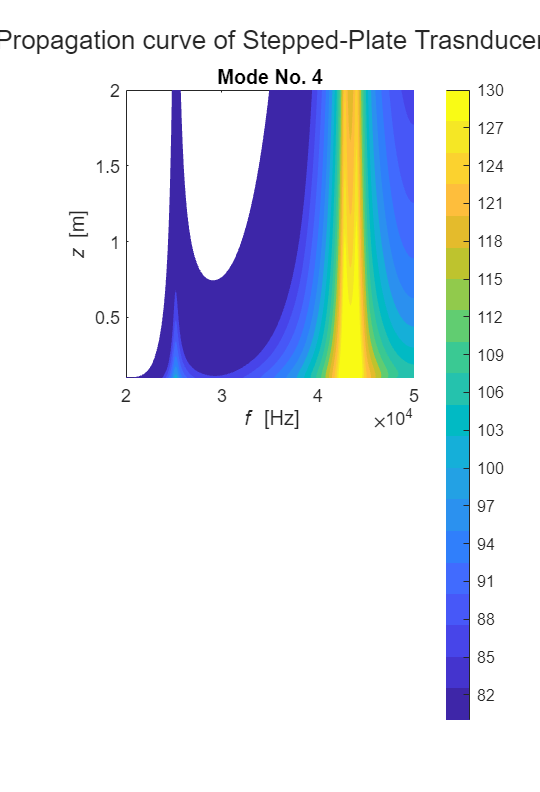

figurePropagationCurveSteppedPlateTransducerAcoustic = figure('Name','f, z vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tilePropagationCurveSteppedPlateTransducerAcoustic = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
C = parula(20);
colormap(C);

% for iMode = 1:1
for iMode = 1:Study.nMode
    axesPropagationCurveSteppedPlateTransducerAcoustic = nexttile(tilePropagationCurveSteppedPlateTransducerAcoustic);
    hold(axesPropagationCurveSteppedPlateTransducerAcoustic,'on');
    
    [tempF, tempZ] = meshgrid(Study.freqAcoustic, Study.z(1,:,iMode));
    pPropagationCurveSteppedPlateTransducerAcoustic = contourf(tempF, tempZ, ...
        Aco.pcSteppedPlateTransducerFEM(:,:,iMode)',70:3:130,'EdgeColor','none');
    % pPropagationCurveSteppedPlateTransducerAcoustic = contourf(tempF, tempZ, ...
    %     Aco.pcSteppedPlateFEM(:,:,iMode)'-repmat(max(Aco.pcSteppedPlateTransducerFEM(:,:,iMode),[],2),1,Study.N_Z)',20,'EdgeColor','none');
    box(axesPropagationCurveSteppedPlateTransducerAcoustic,'on');
    hold(axesPropagationCurveSteppedPlateTransducerAcoustic,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\itz} [m]')
    title(axesPropagationCurveSteppedPlateTransducerAcoustic, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesPropagationCurveSteppedPlateTransducerAcoustic,[Study.Z_START Study.Z_STOP]);
    clim(axesPropagationCurveSteppedPlateTransducerAcoustic,[80 130]);
    hold(axesPropagationCurveSteppedPlateTransducerAcoustic,'off');
end
cbPropagationCurveSteppedPlateTransducerAcoustic = colorbar(axesPropagationCurveSteppedPlateTransducerAcoustic,'Ticks',70:3:130);
cbPropagationCurveSteppedPlateTransducerAcoustic.Layout.Tile = 'east';
title(tilePropagationCurveSteppedPlateTransducerAcoustic,'Propagation curve of Stepped-Plate Trasnducer')

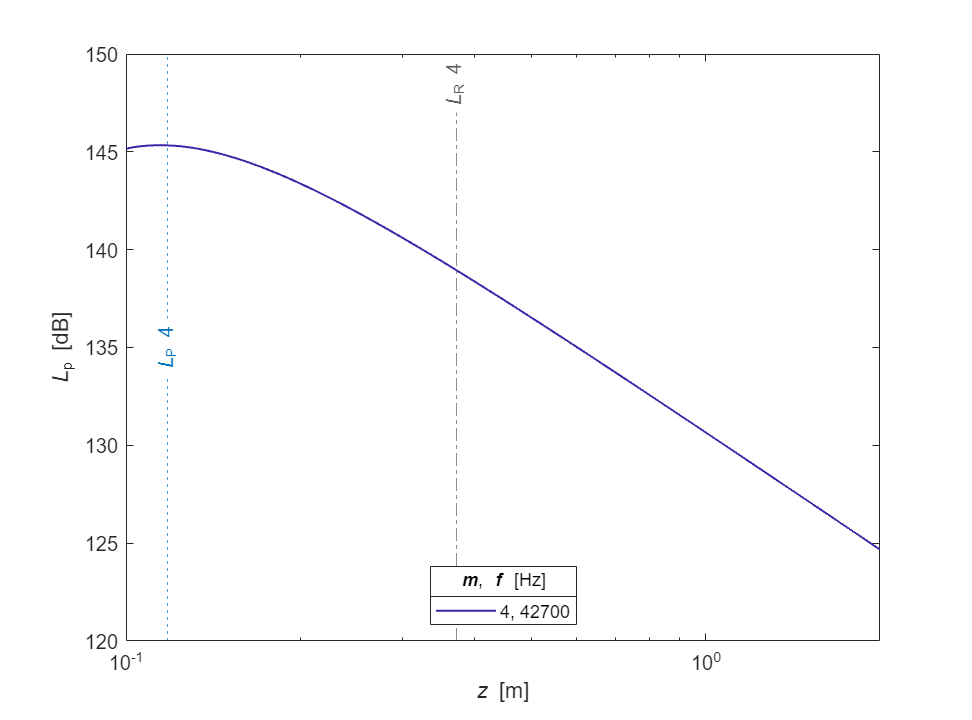

% Peak propagation curve of Stepped-Plate Trasnducer
figurePropagationCurveSteppedPlateTransducerAcousticPeak = figure('Name','z vs. SPL','Units','inches','Position',[0 0 6.75 5]);
axesPropagationCurveSteppedPlateTransducerAcousticPeak = axes('Parent',figurePropagationCurveSteppedPlateTransducerAcousticPeak);
hold(axesPropagationCurveSteppedPlateTransducerAcousticPeak,'on');
C = colororder(parula(Study.nMode+1));
colororder(repmat(C(1:Study.nMode,:),3,1));

[~,iPeakSteppedPlateTransducerFEM] =  max(abs(Plate.uSteppedPlateTransducerAcousticFEM));

for iMode = 1:Study.nMode
    pPropagationCurveSteppedPlateTransducerAcousticPeak = ...
        plot(Study.z(iPeakSteppedPlateTransducerFEM(iMode),:,iMode), ...
        Aco.pcSteppedPlateTransducerFEM(iPeakSteppedPlateTransducerFEM(iMode),:,iMode), ...
        'DisplayName',[num2str(Study.mode(iMode)) ', ' num2str(Study.freqAcoustic(tempI(iMode)))], ...
        'LineWidth',1);
end

pRayleighLengthPeakFreqAcoustic = xline(Aco.computeRayleighLength(Plate.rFEM,Study.freqAcoustic(iPeakSteppedPlateTransducerFEM),Air.c),...
    '-.',repmat("{\itL}_R ",1,Study.nMode)'+string(Study.mode)','HandleVisibility','Off','Color','#5C5C5C', ...
    'LabelHorizontalAlignment','center');
pAxialPeakDistanceFreqAcoustic = xline(Aco.computeAxialPeakDistance(Plate.rFEM,Study.freqAcoustic(iPeakSteppedPlateTransducerFEM),Air.c),...
    ':',repmat("{\itL}_P ",1,Study.nMode)'+string(Study.mode)','HandleVisibility','Off','Color','#0072BD', ...
    'LabelVerticalAlignment','middle','LabelHorizontalAlignment','center');
pAxialNullDistanceFreqAcoustic = xline(Aco.computeAxialNullDistance(Plate.rFEM,Study.freqAcoustic(iPeakSteppedPlateTransducerFEM),Air.c),...
    '--',repmat("{\itL}_N ",1,Study.nMode)'+string(Study.mode)','HandleVisibility','Off','Color','#D95319', ...
    'LabelHorizontalAlignment','center');

box(axesPropagationCurveSteppedPlateTransducerAcousticPeak,'on');
hold(axesPropagationCurveSteppedPlateTransducerAcousticPeak,'off');
xlabel('{\itz} [m]')
ylabel('{\itL}_{p} [dB]')
xlim(axesPropagationCurveSteppedPlateTransducerAcousticPeak,[Study.Z_START Study.Z_STOP]); 
% ylim(axesPropagationCurveSteppedPlateTransducerAcousticPeak,[110 135]);
set(axesPropagationCurveSteppedPlateTransducerAcousticPeak,'XScale','log');
lgdPropagationCurveSteppedPlateTransducerAcousticPeak = legend(axesPropagationCurveSteppedPlateTransducerAcousticPeak,'Location','south','Orientation','vertical');
title(lgdPropagationCurveSteppedPlateTransducerAcousticPeak, '{\itm}{\rm,} {\itf} {\rm[Hz]}')
hold(axesPropagationCurveSteppedPlateTransducerAcousticPeak,'off');

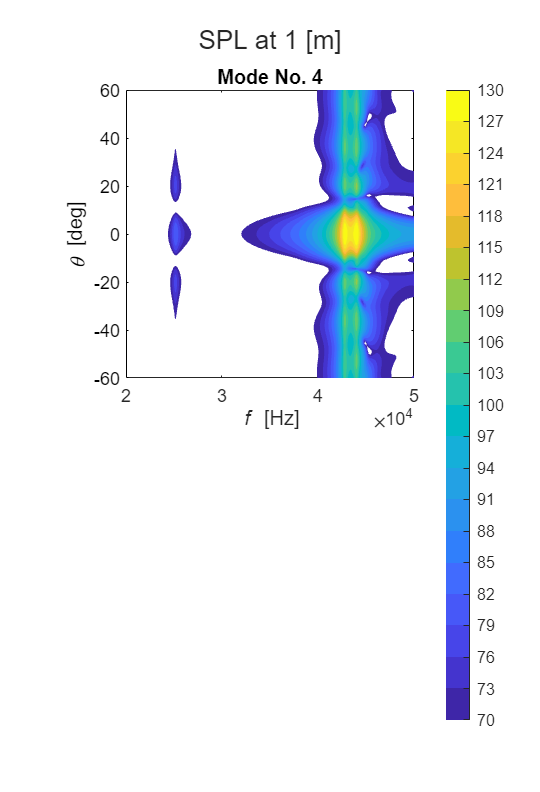

figureBeamPatternSteppedPlateTransducerAcoustic = figure('Name','f, th vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tileBeamPatternSteppedPlateTransducerAcoustic = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
C = parula(20);
colormap(C);

for iMode = 1:Study.nMode
    axesBeamPatternSteppedPlateTransducerAcoustic = nexttile(tileBeamPatternSteppedPlateTransducerAcoustic);
    hold(axesBeamPatternSteppedPlateTransducerAcoustic,'on');

    [tempF, tempTh] = meshgrid(Study.freqAcoustic, Study.th(1,:,iMode));
    pBeamPatternSteppedPlateTransducerAcoustic = contourf(tempF, tempTh/pi*180, ...
        Aco.bpSteppedPlateTransducerFEM(:,:,iMode)',70:3:130,'EdgeColor','none');

    set(axesBeamPatternSteppedPlateTransducerAcoustic,'YColor',[0 0 0]);
    box(axesBeamPatternSteppedPlateTransducerAcoustic,'on');
    hold(axesBeamPatternSteppedPlateTransducerAcoustic,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\it\theta} [deg]')
    title(axesBeamPatternSteppedPlateTransducerAcoustic, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesBeamPatternSteppedPlateTransducerAcoustic,[Study.TH_START/pi*180/1.5 Study.TH_STOP/pi*180/1.5]);
    clim(axesBeamPatternSteppedPlateTransducerAcoustic,[70 130])
    hold(axesBeamPatternSteppedPlateTransducerAcoustic,'off');
end
cbBeamPatternSteppedPlateTransducerAcoustic = colorbar(axesBeamPatternSteppedPlateTransducerAcoustic,'Ticks',70:3:130);
cbBeamPatternSteppedPlateTransducerAcoustic.Layout.Tile = 'east';
title(tileBeamPatternSteppedPlateTransducerAcoustic,'SPL at 1 [m]')

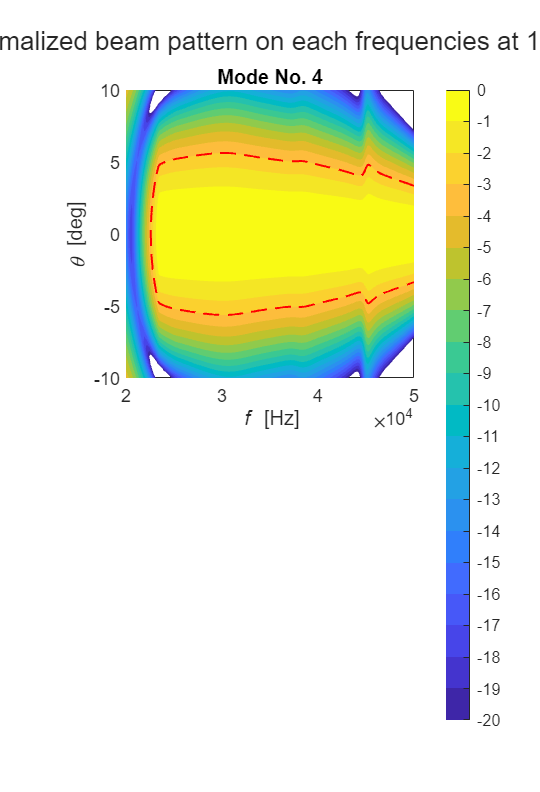

figureBeamPatternSteppedPlateTransducerAcousticNormalized = figure('Name','f, th vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tileBeamPatternSteppedPlateTransducerAcousticNormalized = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
C = parula(20);
colormap(C);

for iMode = 1:Study.nMode
    axesBeamPatternSteppedPlateTransducerAcousticNormalized = nexttile(tileBeamPatternSteppedPlateTransducerAcousticNormalized);
    hold(axesBeamPatternSteppedPlateTransducerAcousticNormalized,'on');
    
    [tempF, tempTh] = meshgrid(Study.freqAcoustic, Study.th(1,:,iMode));
    Aco.bpNormalizedSteppedPlateTransducerFEM = ...
        Aco.bpSteppedPlateTransducerFEM(:,:,iMode)'-repmat(max(Aco.bpSteppedPlateTransducerFEM(:,:,iMode),[],2),1,Study.N_TH)';
    pBeamPatternSteppedPlateTransducerTransducerAcousticNormalized = contourf(tempF, tempTh/pi*180, ...
        Aco.bpNormalizedSteppedPlateTransducerFEM,-20:0,'EdgeColor','none');
    pHalfPowerBeamWidthNormalized = contour(tempF, tempTh/pi*180, ...
        Aco.bpNormalizedSteppedPlateTransducerFEM,[-3 -3],'--r','LineWidth',1);

    box(axesBeamPatternSteppedPlateTransducerAcousticNormalized,'on');
    hold(axesBeamPatternSteppedPlateTransducerAcousticNormalized,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\it\theta} [deg]')
    title(axesBeamPatternSteppedPlateTransducerAcousticNormalized, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesBeamPatternSteppedPlateTransducerAcousticNormalized,[Study.TH_START/pi*180/9 Study.TH_STOP/pi*180/9]);
    clim(axesBeamPatternSteppedPlateTransducerAcousticNormalized,[-20 0])
    hold(axesBeamPatternSteppedPlateTransducerAcousticNormalized,'off');
end
cbBeamPatternSteppedPlateTransducerAcousticNormalized = colorbar(axesBeamPatternSteppedPlateTransducerAcousticNormalized,'Ticks',-20:0);
cbBeamPatternSteppedPlateTransducerAcousticNormalized.Layout.Tile = 'east';
title(tileBeamPatternSteppedPlateTransducerAcousticNormalized,'Normalized beam pattern on each frequencies at 1 [m]')

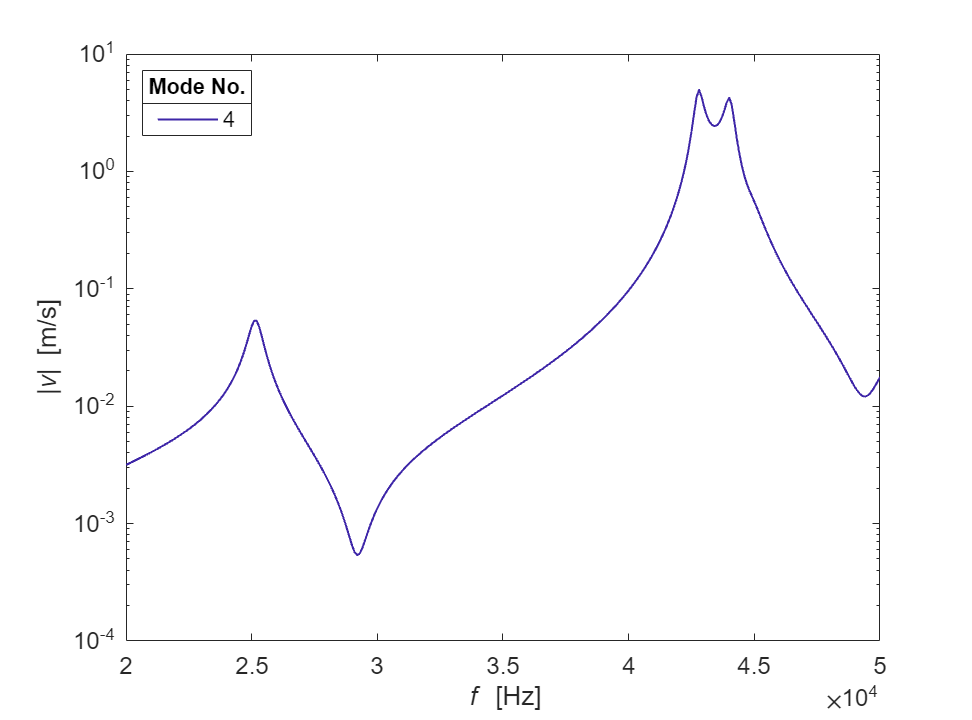

% Distributed Parameter Model
figureU5SteppedPlateTransducerAcousticFEM = figure('Name','f vs. Z','Units','inches','Position',[0 0 6.75 5]);

axesU5SteppedPlateTransducerAcousticFEM = axes('Parent',figureU5SteppedPlateTransducerAcousticFEM);
hold(axesU5SteppedPlateTransducerAcousticFEM,'on');
C = colororder(parula(Study.nMode+1));
colororder(C(1:Study.nMode,:));

pU5SteppedPlateTransducerAcousticFEM = semilogy(Study.freqAcoustic, abs(Plate.uSteppedPlateTransducerAcousticFEM),'LineWidth',1);
% pU5DPM = semilogy(Study.freqSolid, abs(DPM.u5),'LineWidth',1,'LineStyle','-.');

set(axesU5SteppedPlateTransducerAcousticFEM,'YMinorTick','on','YScale','log','FontSize',12);
box(axesU5SteppedPlateTransducerAcousticFEM,'on');
hold(axesU5SteppedPlateTransducerAcousticFEM,'off');
xlabel('{\itf} [Hz]')
ylabel('|{\itv}| [m/s]')
% xlim(axesU5SteppedPlateTransducerAcousticFEM,[Plate.FREQ*0.97 Plate.FREQ*1.03]);
% ylim(axesU5SteppedPlateTransducerAcousticFEM,[5e-2 10]);
lgdU5SteppedPlateTransducerAcousticFEM = legend(pU5SteppedPlateTransducerAcousticFEM, string(Study.MODE_NO_START:Study.MODE_NO_STOP),'Location','northwest','Orientation','vertical');
title(lgdU5SteppedPlateTransducerAcousticFEM, 'Mode No.')
hold(axesU5SteppedPlateTransducerAcousticFEM,'off');

% Get index of the frequencies of the second maximum velocity
for iMode = 1:Study.nMode
    [tempPks,tempLocs] = findpeaks(abs(Plate.uSteppedPlateTransducerAcousticFEM(:,iMode)));
    [~,tempI] = sort(tempPks,'descend');
    tempI = tempLocs(tempI);
    iFirstPeakSteppedPlateTransducerAcousticFEM(iMode) = tempI(1);
    iSecondPeakSteppedPlateTransducerAcousticFEM(iMode) = tempI(2);
end

Aco.l = 1.2;
Aco.zObs = 0.5;

% for iMode = 1:1
for iMode = 1:Study.nMode
    tic
    tempFilename = ['computeSteppedPlateTransducerAcousticSecondary_r=' num2str(Plate.rFEM(iMode)*1e3,'%2.1f')...
        '_t=' num2str(Plate.THICKNESS*1e3,'%2.1f')...
        '_m=' num2str(Study.mode(iMode),'%d')...
        '_f=' num2str(Plate.FREQ/1e3, '%g')...
        '.mph'];
    if exist(tempFilename,'file') == 2
        modelComputeSteppedPlateTransducerAcousticSecondary = mphload(tempFilename);
    elseif exist('modelComputeSteppedPlateTransducerAcousticSecondary','var') ~= 1
        modelComputeSteppedPlateTransducerAcousticSecondary = mphload('computeSteppedPlateTransducerAcousticSecondary.mph');
        modelComputeSteppedPlateTransducerAcousticSecondary.hist.disable;

        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Study_zStart',      [num2str(Study.Z_START)     ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Study_zStop',       [num2str(Study.Z_STOP_ACO_SEC)   ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Study_thStart',     num2str(Study.TH_START));
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Study_thStop',      num2str(Study.TH_STOP));
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Plate_t',           [num2str(Plate.THICKNESS)   ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Plate_r',           [num2str(Plate.rFEM(iMode)) ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Plate_tStep',       [num2str(Plate.tStep) ' [m]']);
    
        tempRStep = cell2mat(Plate.rStepFEM(iMode));
        for iStep = 1:fix(length(tempRStep)/2)  % fix(5/2)=2, fix(6/2)=3
            tag = modelComputeSteppedPlateTransducerAcousticSecondary.geom('geom1').feature.uniquetag('r');
            modelComputeSteppedPlateTransducerAcousticSecondary.geom('geom1').feature.create(tag, 'Rectangle');
            modelComputeSteppedPlateTransducerAcousticSecondary.geom('geom1').feature(tag).set('size', [tempRStep(2*iStep)-tempRStep(2*iStep-1) Plate.tStep]);
            modelComputeSteppedPlateTransducerAcousticSecondary.geom('geom1').feature(tag).set('pos',  [tempRStep(2*iStep-1) 0]);
        end

        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_l1',           [num2str(Xdcr.l(1)) ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_l2',           [num2str(Xdcr.l(2)) ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_l3',           [num2str(Xdcr.l(3)) ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_l4',           [num2str(Xdcr.l(4)) ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_r1',           [num2str(Xdcr.r(1)) ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_r2',           [num2str(Xdcr.r(2)) ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_r3',           [num2str(Xdcr.r(3)) ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_r4',           [num2str(Xdcr.r(4)) ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_nPiezo',       num2str(Xdcr.nPiezo));
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Xdcr_V',            [num2str(Xdcr.V)    ' [V]']);

        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Aco_l',             [num2str(Aco.l)     ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Aco_zObs',          [num2str(Aco.zObs)  ' [m]']);
        modelComputeSteppedPlateTransducerAcousticSecondary.param.set('Aco_fc', ...
            [num2str(Study.freqAcoustic(iSecondPeakSteppedPlateTransducerAcousticFEM(iMode)))    ' [Hz]']);
        
        mphrun(modelComputeSteppedPlateTransducerAcousticSecondary,'std1')               
        mphsave(modelComputeSteppedPlateTransducerAcousticSecondary,[Env.MPH.PATH tempFilename])
    end

    Plate.uSteppedPlateTransducerAcousticSecondaryCarrierFEM(:,iMode) = ...
        mphevalpoint(modelComputeSteppedPlateTransducerAcousticSecondary, 'solidc.u_tZ', 'dataset', 'dset1','selection','box1');
    Plate.uSteppedPlateTransducerAcousticSecondarySidebandFEM(:,iMode) = ...
        mphevalpoint(modelComputeSteppedPlateTransducerAcousticSecondary, 'solids.u_tZ', 'dataset', 'dset1','selection','box1');
    [Study.zAcousticSecondary(:,:,iMode), Aco.pcSteppedPlateTransducerAcousticSecondaryCarrier(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateTransducerAcousticSecondary,{'z' 'at2(0, z, acprc.Lp_t)'},'dataset','grid1');
    [Study.zAcousticSecondary(:,:,iMode), Aco.pcSteppedPlateTransducerAcousticSecondarySideband(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateTransducerAcousticSecondary,{'z' 'at2(0, z, acprs.Lp_t)'},'dataset','grid1');
    [Study.zAcousticSecondary(:,:,iMode), Aco.pcSteppedPlateTransducerAcousticSecondaryDifference(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateTransducerAcousticSecondary,{'z' 'at2(0, z, acprd.Lp_t)'},'dataset','grid1');
    [Study.thAcousticSecondary(:,:,iMode), Aco.bpSteppedPlateTransducerAcousticSecondaryCarrier(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateTransducerAcousticSecondary, ...
        {'th' 'subst(acprc.efc1.Lp_pextc,r,2*Study_zStop*sin(th),z,2*Study_zStop*cos(th))'},'dataset','grid2');
    [Study.thAcousticSecondary(:,:,iMode), Aco.bpSteppedPlateTransducerAcousticSecondarySideband(:,:,iMode)] = ...
        mphinterp(modelComputeSteppedPlateTransducerAcousticSecondary, ...
        {'th' 'subst(acprs.efc1.Lp_pexts,r,2*Study_zStop*sin(th),z,2*Study_zStop*cos(th))'},'dataset','grid2');

    clear modelComputeSteppedPlateTransducerAcousticSecondary
    toc
end

Elapsed time is 67.997959 seconds.


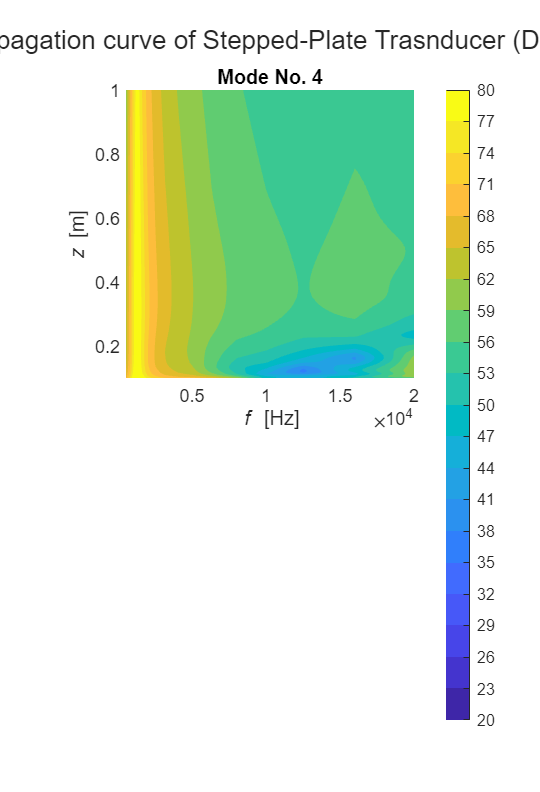

figurePropagationCurveSteppedPlateTransducerAcousticSecDiff = figure('Name','f, z vs. SPL','Units','inches','Position',[0 0 3.25*ceil(Study.nMode/2)+0.5 2.5*2+0.5]);
tilePropagationCurveSteppedPlateTransducerAcousticSecDiff = tiledlayout(2,ceil(Study.nMode/2),'TileIndexing','columnmajor','TileSpacing','tight', ...
    'Unit','inches','Position',[0.625+0.25 0.5 3.25*ceil(Study.nMode/2)-1.25 2.5*2-0.625]);
C = parula(20);
colormap(C);

% for iMode = 1:1
for iMode = 1:Study.nMode
    axesPropagationCurveSteppedPlateTransducerAcousticSecDiff = nexttile(tilePropagationCurveSteppedPlateTransducerAcousticSecDiff);
    hold(axesPropagationCurveSteppedPlateTransducerAcousticSecDiff,'on');
    
    [tempF, tempZ] = meshgrid(Study.freqAcousticSecDiff, Study.z(1,:,iMode));
    pPropagationCurveSteppedPlateTransducerAcousticSecDiff = contourf(tempF, tempZ, ...
        Aco.pcSteppedPlateTransducerAcousticSecondaryDifference(:,:,iMode)',20:3:80,'EdgeColor','none');
    % pPropagationCurveSteppedPlateTransducerAcousticSecDiff = contourf(tempF, tempZ, ...
    %     Aco.pcSteppedPlateFEM(:,:,iMode)'-repmat(max(Aco.pcSteppedPlateTransducerFEM(:,:,iMode),[],2),1,Study.N_Z)',20,'EdgeColor','none');
    box(axesPropagationCurveSteppedPlateTransducerAcousticSecDiff,'on');
    hold(axesPropagationCurveSteppedPlateTransducerAcousticSecDiff,'off');
    xlabel('{\itf} [Hz]')
    ylabel('{\itz} [m]')
    title(axesPropagationCurveSteppedPlateTransducerAcousticSecDiff, ['Mode No. ' num2str(Study.mode(iMode))])
    ylim(axesPropagationCurveSteppedPlateTransducerAcousticSecDiff,[Study.Z_START Study.Z_STOP_ACO_SEC]);
    clim(axesPropagationCurveSteppedPlateTransducerAcousticSecDiff,[20 80]);
    hold(axesPropagationCurveSteppedPlateTransducerAcousticSecDiff,'off');
    % colorbar(axesPropagationCurveSteppedPlateTransducerAcousticSecDiff);
end
cbPropagationCurveSteppedPlateTransducerAcousticSecondary = colorbar(axesPropagationCurveSteppedPlateTransducerAcousticSecDiff,'Ticks',20:3:80);
cbPropagationCurveSteppedPlateTransducerAcousticSecondary.Layout.Tile = 'east';
title(tilePropagationCurveSteppedPlateTransducerAcousticSecDiff,'Propagation curve of Stepped-Plate Trasnducer (DFG)')

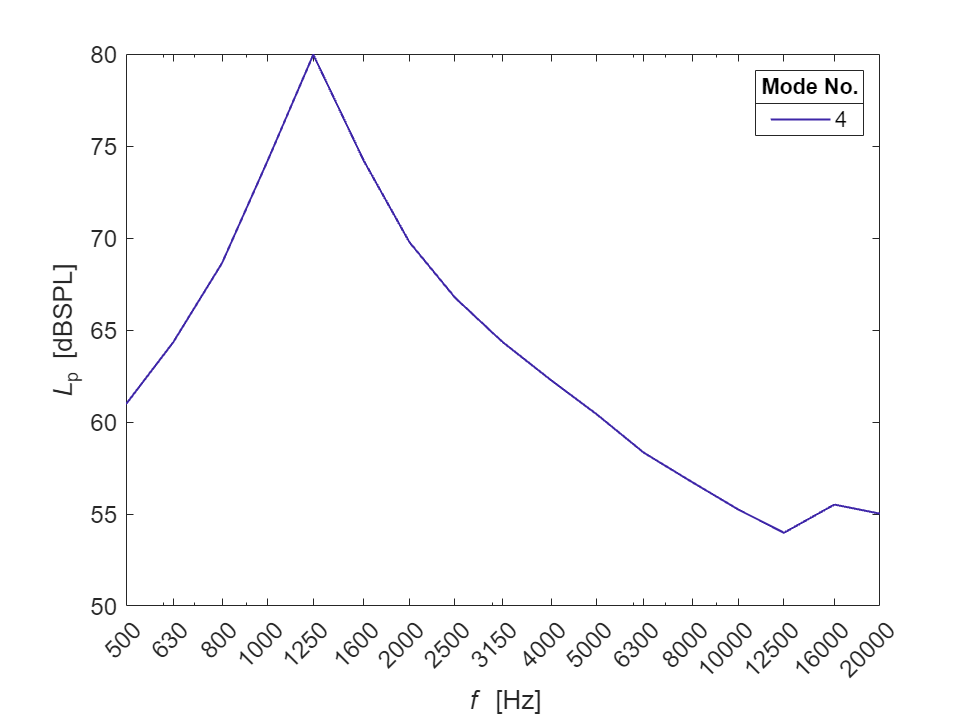

[~,iZObsSteppedPlateTransducerAcousticSecondary] = min(abs(Study.zAcousticSecondary(1,:,:)-Aco.zObs),[],2);
for iMode = 1:Study.nMode
    Aco.frSteppedPlateTransducerAcousticSecondaryDiff(:,iMode) = ...
        Aco.pcSteppedPlateTransducerAcousticSecondaryDifference(:,squeeze(iZObsSteppedPlateTransducerAcousticSecondary(1,:,iMode)),iMode);
end

figureFrSteppedPlateTransducerAcousticSecondaryDiff = figure('Name','f vs. Z','Units','inches','Position',[0 0 6.75 5]);

axesFrSteppedPlateTransducerAcousticSecondaryDiff = axes('Parent',figureFrSteppedPlateTransducerAcousticSecondaryDiff);
hold(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'on');
C = colororder(parula(Study.nMode+1));
colororder(C(1:Study.nMode,:));

pFrSteppedPlateTransducerAcousticSecondaryDiff = plot(Study.freqAcousticSecDiff, Aco.frSteppedPlateTransducerAcousticSecondaryDiff,'LineWidth',1);
% pU5DPM = semilogy(Study.freqSolid, abs(DPM.u5),'LineWidth',1,'LineStyle','-.');

set(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'XScale','log','YScale','linear','FontSize',12);
box(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'on');
hold(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'off');
xlabel('{\itf} [Hz]')
xticks(Study.freqAcousticSecDiff)
xticklabels(string(Study.freqAcousticSecDiff))
ylabel('{\itL}_p [dBSPL]')
% xlim(axesFrSteppedPlateTransducerAcousticSecondaryDiff,[Plate.FREQ*0.97 Plate.FREQ*1.03]);
% ylim(axesFrSteppedPlateTransducerAcousticSecondaryDiff,[5e-2 10]);
lgdFrSteppedPlateTransducerAcousticSecondaryDiff = ...
    legend(pFrSteppedPlateTransducerAcousticSecondaryDiff, string(Study.MODE_NO_START:Study.MODE_NO_STOP), ...
    'Location','northeast','Orientation','vertical');
title(lgdFrSteppedPlateTransducerAcousticSecondaryDiff, 'Mode No.')
hold(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'off')

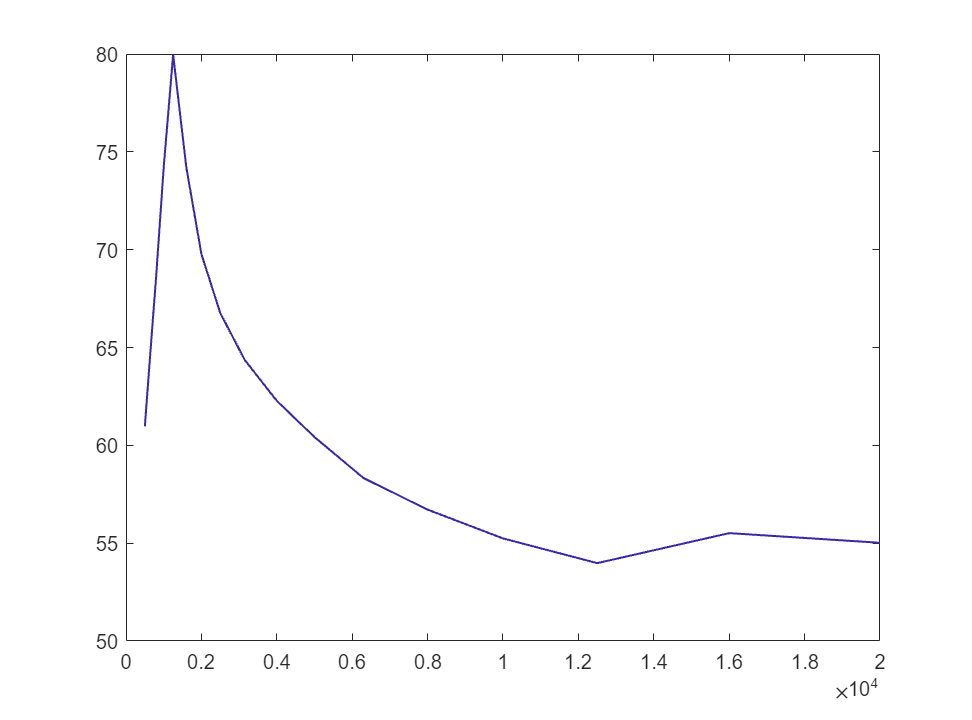

pFrSteppedPlateTransducerAcousticSecondaryDiff =   Line with properties:

              Color: [0.2422 0.1504 0.6603]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [500 630 800 1000 1250 1600 2000 2500 3150 4000 5000 6300 8000 10000 12500 16000 20000]
              YData: [60.9688 64.3353 68.6398 74.2073 79.9663 74.2034 69.7773 66.7617 64.3623 62.2732 60.4218 58.3289 56.7148 55.2431 53.9793 55.5130 55.0200]

  Show all properties


for iMode = 1:Study.nMode
    surf(tempF, tempZ, ...
        Aco.pcSteppedPlateTransducerAcousticSecondaryDifference(:,:,iMode)', ...
        'EdgeColor','none','FaceColor',C(iMode,:))
    hold on
end
hold off
view(2)

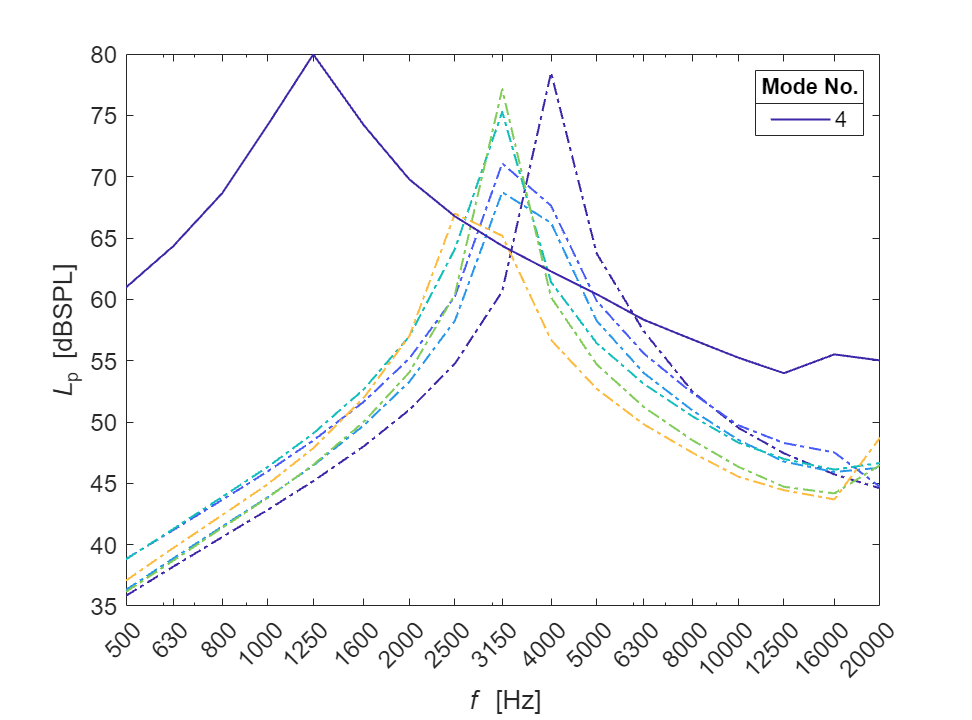

[~,iZObsSteppedPlateTransducerAcousticSecondary] = min(abs(Study.zAcousticSecondary(1,:,:)-Aco.zObs),[],2);
for iMode = 1:Study.nMode
    Aco.frSteppedPlateTransducerAcousticSecondaryDiff(:,iMode) = ...
        Aco.pcSteppedPlateTransducerAcousticSecondaryDifference(:,squeeze(iZObsSteppedPlateTransducerAcousticSecondary(1,:,iMode)),iMode);
end

figureFrSteppedPlateTransducerAcousticSecondaryDiff = figure('Name','f vs. Z','Units','inches','Position',[0 0 6.75 5]);

axesFrSteppedPlateTransducerAcousticSecondaryDiff = axes('Parent',figureFrSteppedPlateTransducerAcousticSecondaryDiff);
hold(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'on');
C = colororder(parula(6+1));
colororder(C(1:6,:));

pFrSteppedPlateTransducerAcousticSecondaryDiff1 = plot(Study.freqAcousticSecDiff, tempfrSteppedPlateTransducerAcousticSecondaryDiff,'LineWidth',1,'LineStyle','-.');
pFrSteppedPlateTransducerAcousticSecondaryDiff = plot(Study.freqAcousticSecDiff, Aco.frSteppedPlateTransducerAcousticSecondaryDiff,'LineWidth',1);

set(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'XScale','log','YScale','linear','FontSize',12);
box(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'on');
hold(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'off');
xlabel('{\itf} [Hz]')
xticks(Study.freqAcousticSecDiff)
xticklabels(string(Study.freqAcousticSecDiff))
ylabel('{\itL}_p [dBSPL]')
% xlim(axesFrSteppedPlateTransducerAcousticSecondaryDiff,[Plate.FREQ*0.97 Plate.FREQ*1.03]);
% ylim(axesFrSteppedPlateTransducerAcousticSecondaryDiff,[5e-2 10]);
lgdFrSteppedPlateTransducerAcousticSecondaryDiff = ...
    legend(pFrSteppedPlateTransducerAcousticSecondaryDiff, string(Study.MODE_NO_START:Study.MODE_NO_STOP), ...
    'Location','northeast','Orientation','vertical');
title(lgdFrSteppedPlateTransducerAcousticSecondaryDiff, 'Mode No.')
hold(axesFrSteppedPlateTransducerAcousticSecondaryDiff,'off')

% 이 결과로 음향 해석 해보자
% 
% 트랜스듀서의 출력은 어짜피 정해져 있음
% 
% 플레이트 임피던스에 따라서 속도가 정해짐
% 
% 음향으로 더 큰 Primary가 나와야 함
% 
% 이렇지가 않으면 플레이트의 반경을 유지하고 주파수를 낮추고 낮은 모드로 구동 시켜야하는데 이러면 레일리 디스턴스를 줄일 수 있음
% 
% 플레이트의 크기를 유지한채.
% 
% 그리고 주파수를 줄이면 반경이 더 큰 압전을 사용할 수 있음
% 
% 이것이 제일 베스트일 수도 있다.
